# Levenberg-Marquadt

clearvars, clc

## Read Data

T = readtable('_discreteParameters.txt', 'FileType', 'text', 'Delimiter', '\t');
data = readmatrix('A1-007-DST-US06-FUDS-25-20120827.xlsx', 'Sheet', 'Sheet1');

## Initialization

Ut       = data(:,5)';
I        = data(:,4)';
TestTime = data(:,1)';
dt       = [diff(TestTime), diff(TestTime(end-1:end))];

Theta    = T{:,:}';

N        = numel(Ut);
delta    = 1e-6;           % FD step
mu0      = 1e3;            % initial damping
c1       = 0.1;            % factor turun
c2       = 10;             % factor naik
maxIter  = 20;
tol      = 1e-2;

% Pre-allocate hasil
ParamsLM = zeros(6, N);

## Run LM

warning("off", "MATLAB:nearlySingularMatrix");
warning("off", "MATLAB:singularMatrix");

for k = 3:N
    Ts    = dt(k);
    th    = Theta(:,k);

    % Inisialisasi params dari inversi Theta→RC
    [R0, R1, R2, C1, C2] = theta2rc(th, Ts);
    Uoc   = th(6)/(1-th(1)-th(2));
    params = [R0; R1; R2; C1; C2; Uoc];

    mu = mu0;
    % LM kecil untuk refine params pada k
    for it = 1:maxIter
        % 1) hitung theta_model(6×1)
        theta_model = rc2theta_scalar(params, Ts);

        % 2) residual 6×1
        r = theta_model - th;

        % 3) Jacobian FD 6×6
        J = zeros(6,6);
        for j = 1:6
            p_tmp = params;
            p_tmp(j) = p_tmp(j) + delta;
            th_tmp = rc2theta_scalar(p_tmp, Ts);
            J(:,j) = (th_tmp - theta_model)/delta;
        end

        % 4) gradient & GN‐Hessian
        g  = J' * r;      % 6×1
        H  = J' * J;      % 6×6

        % 5) damping & step
        mu = max(mu, 1e-6);
        Hm = H + mu*diag(diag(H));
        dp = - Hm \ g;    % 6×1

        % 6) coba update
        params_new  = params + dp;
        theta_new   = rc2theta_scalar(params_new, Ts);
        r_new       = theta_new - th;

        if norm(r_new) < norm(r)
            if norm(r - r_new) < tol
                break
            end
            
            params = params_new;
            mu     = max(mu*c1, 1e-12);
        else
            mu = mu * c2;
        end
    end

    ParamsLM(:,k) = params;
end

## Graph Data

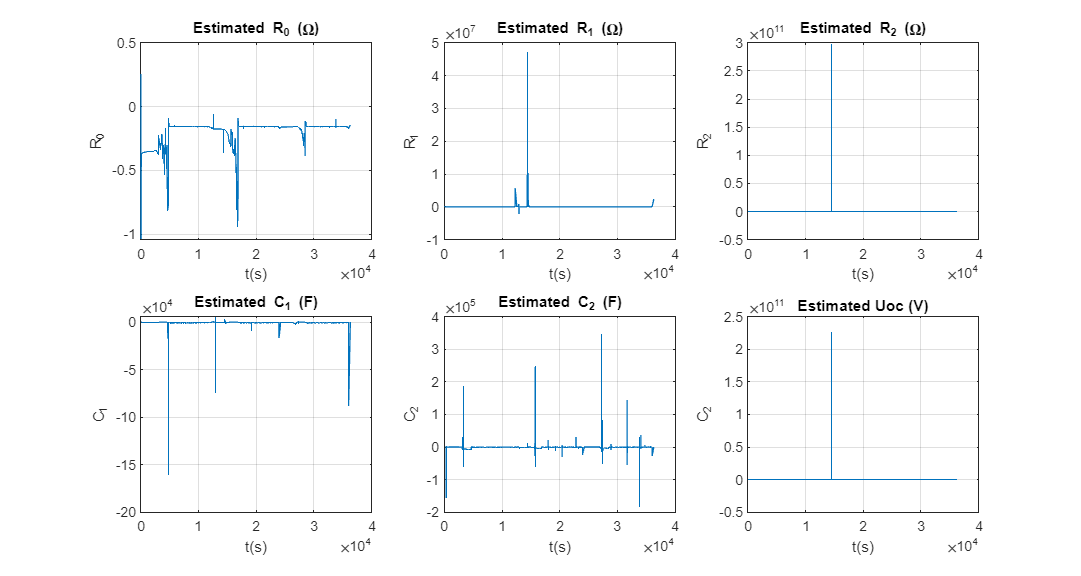

R0 = ParamsLM(1,:); R1 = ParamsLM(2,:); R2 = ParamsLM(3,:);
C1 = ParamsLM(4,:); C2 = ParamsLM(5,:); Uoc = ParamsLM(6,:);

figure('Name','Estimated Battery Parameters','NumberTitle','off');
set(gcf,'Position',[100, 100, 1500, 800]);

% Baris 1: R0, R1, R2
subplot(2,3,1);
plot(TestTime, R0);
title('Estimated R_0 (\Omega)');
xlabel('t(s)'); ylabel('R_0'); grid on;

subplot(2,3,2);
plot(TestTime, R1);
title('Estimated R_1 (\Omega)');
xlabel('t(s)'); ylabel('R_1'); grid on;

subplot(2,3,3);
plot(TestTime, R2);
title('Estimated R_2 (\Omega)');
xlabel('t(s)'); ylabel('R_2'); grid on;

subplot(2,3,4);
plot(TestTime, C1);
title('Estimated C_1 (F)');
xlabel('t(s)'); ylabel('C_1'); grid on;

subplot(2,3,5);
plot(TestTime, C2);
title('Estimated C_2 (F)');
xlabel('t(s)'); ylabel('C_2'); grid on;

subplot(2,3,6);
plot(TestTime, Uoc);
title('Estimated Uoc (V)');
xlabel('t(s)'); ylabel('C_2'); grid on;

## Compare Performance

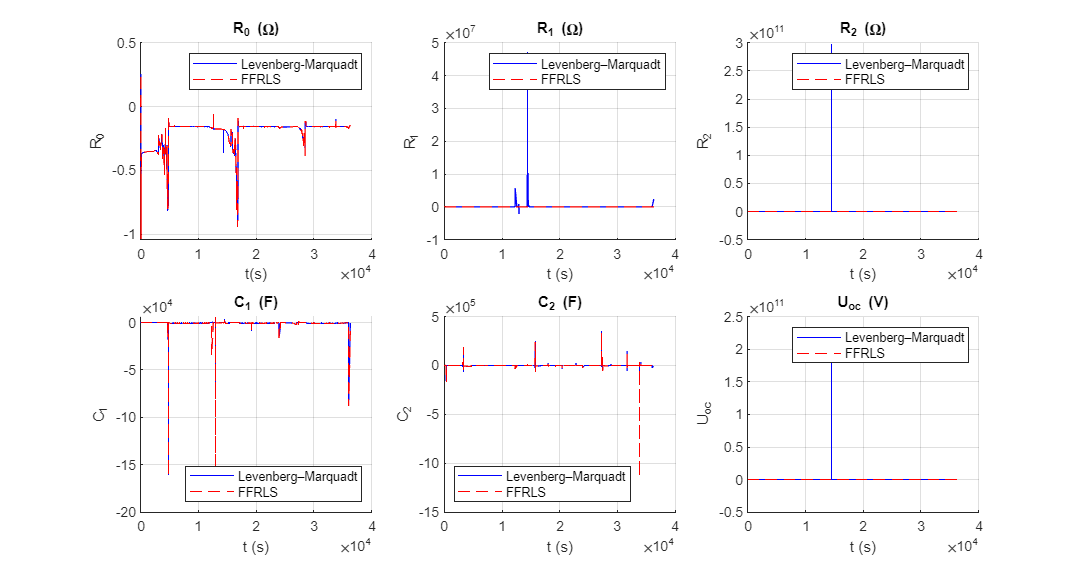

T = readtable('_FFRLSParameters.txt', 'FileType', 'text', 'Delimiter', '\t');

figure('Name','Parameter Value Comparison','NumberTitle','off');
set(gcf,'Position',[100, 100, 1500, 800]);

% Subplot 1: R0
subplot(2,3,1);
hold on;
plot(TestTime, R0, 'b-', 'DisplayName', 'Levenberg-Marquadt');
plot(TestTime, T.R0, 'r--', 'DisplayName', 'FFRLS');
title('R_0 (\Omega)');
legend('Location','northeast');
xlabel('t(s)'); 
ylabel('R_0'); 
grid on;
hold off;

% Subplot 2: R1
subplot(2,3,2);
hold on;
plot(TestTime, R1,    'b-',  'DisplayName','Levenberg–Marquadt');
plot(TestTime, T.R1,  'r--', 'DisplayName','FFRLS');
hold off;
title('R_1 (\Omega)');
legend('Location','northeast');
xlabel('t (s)');
ylabel('R_1');
grid on;

% Subplot 3: R2
subplot(2,3,3);
hold on;
plot(TestTime, R2,    'b-',  'DisplayName','Levenberg–Marquadt');
plot(TestTime, T.R2,  'r--', 'DisplayName','FFRLS');
hold off;
title('R_2 (\Omega)');
legend('Location','northeast');
xlabel('t (s)');
ylabel('R_2');
grid on;

% Subplot 4: C1
subplot(2,3,4);
hold on;
plot(TestTime, C1,    'b-',  'DisplayName','Levenberg–Marquadt');
plot(TestTime, T.C1,  'r--', 'DisplayName','FFRLS');
hold off;
title('C_1 (F)');
legend('Location','southeast');
xlabel('t (s)');
ylabel('C_1');
grid on;

% Subplot 5: C2
subplot(2,3,5);
hold on;
plot(TestTime, C2,    'b-',  'DisplayName','Levenberg–Marquadt');
plot(TestTime, T.C2,  'r--', 'DisplayName','FFRLS');
hold off;
title('C_2 (F)');
legend('Location','southwest');
xlabel('t (s)');
ylabel('C_2');
grid on;

% Subplot 6: Uoc
subplot(2,3,6);
hold on;
plot(TestTime, Uoc,     'b-',  'DisplayName','Levenberg–Marquadt');
plot(TestTime, T.Uoc,   'r--', 'DisplayName','FFRLS');
hold off;
title('U_{oc} (V)');
legend('Location','northeast');
xlabel('t (s)');
ylabel('U_{oc}');
grid on;

## Compare Performance (Cont.)

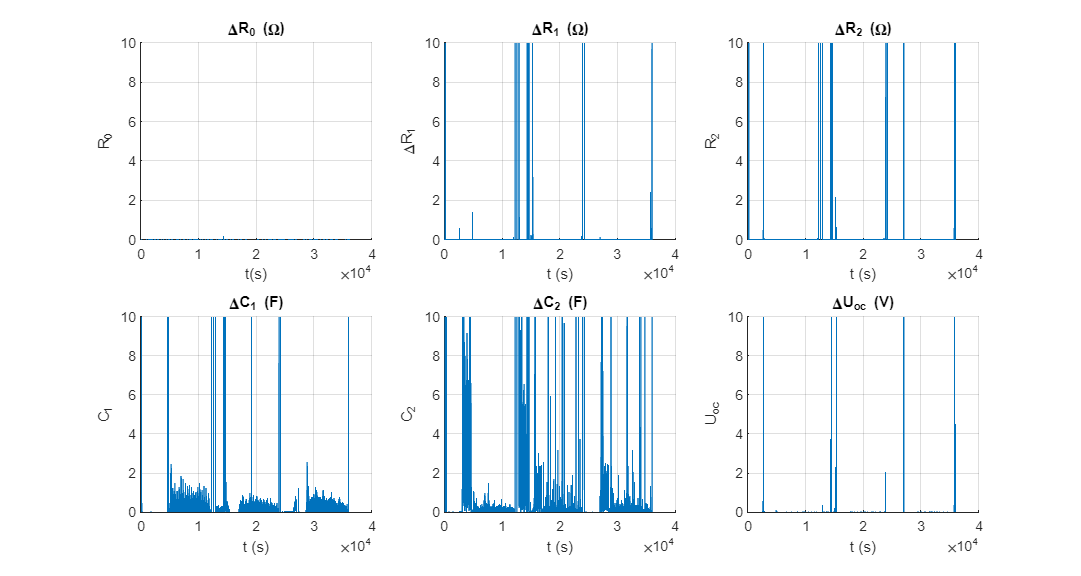

figure('Name','Parameter Value Comparison','NumberTitle','off');
set(gcf,'Position',[100, 100, 1500, 800]);

% Subplot 1: R0
subplot(2,3,1);
hold on;
plot(TestTime, abs(R0' - T.R0));
title('\DeltaR_0 (\Omega)');
xlabel('t(s)'); 
ylabel('R_0'); 
grid on;
ylim([0, 10]);
hold off;

% Subplot 2: R1
subplot(2,3,2);
hold on;
plot(TestTime, abs(R1' - T.R1));
hold off;
title('\DeltaR_1 (\Omega)');
xlabel('t (s)');
ylabel('\DeltaR_1');
ylim([0, 10]);
grid on;

% Subplot 3: R2
subplot(2,3,3);
hold on;
plot(TestTime, abs(R2' - T.R2));
hold off;
title('\DeltaR_2 (\Omega)');
xlabel('t (s)');
ylabel('R_2');
ylim([0, 10]);
grid on;

% Subplot 4: C1
subplot(2,3,4);
hold on;
plot(TestTime, abs(C1' - T.C1));
hold off;
title('\DeltaC_1 (F)');
xlabel('t (s)');
ylabel('C_1');
ylim([0, 10]);
grid on;

% Subplot 5: C2
subplot(2,3,5);
hold on;
plot(TestTime, abs(C2' - T.C2));
hold off;
title('\DeltaC_2 (F)');
xlabel('t (s)');
ylabel('C_2');
ylim([0, 10]);
grid on;

% Subplot 6: Uoc
subplot(2,3,6);
hold on;
plot(TestTime, abs(Uoc' - T.Uoc));
hold off;
title('\DeltaU_{oc} (V)');
xlabel('t (s)');
ylabel('U_{oc}');
ylim([0, 10]);
grid on;

## Save Parameters

params = [R0', R1', R2', C1', C2', Uoc'];

fileID = fopen('_LMParameters.txt','w');
fprintf(fileID, 'R0\tR1\tR2\tC1\tC2\tUoc\n');

for i = 1:size(params,1)
    fprintf(fileID, '%.6f\t%.6f\t%.6f\t%.6f\t%.6f\t%.6f\n', params(i,1), params(i,2), params(i,3), params(i,4), params(i,5), params(i,6));
end

fclose(fileID);

function [R0,R1,R2,C1,C2] = theta2rc(theta,Ts)
  th1=theta(1); th2=theta(2); th3=theta(3);
  th4=theta(4); th5=theta(5);

  a = (th4-th3-th5)/(1+th1-th2);
  b = Ts^2*(1+th1-th2)/(4*(1-th1-th2));
  c = Ts*(1+th2)/(1-th1-th2);
  d = -(th3+th4+th5)/(1-th1-th2);
  f = Ts*(th5-th3)/(1-th1-th2);

  disc = c^2 - 4*b;
  if disc < 1e-8, disc = 1e-8; end
  tau1 = (c + sqrt(disc))/2;
  tau2 = (c - sqrt(disc))/2;
  if abs(tau1-tau2) < 1e-6, tau2 = tau1*(1-1e-3); end

  R0 = a;
  R1 = (tau1*(d-a)+a*c-f)/(tau1-tau2);
  if abs(R1)<1e-6, R1 = sign(R1)*1e-6; end
  R2 = d - a - R1;
  if abs(R2)<1e-6, R2 = sign(R2)*1e-6; end

  C1 = tau1 / R1;
  C2 = tau2 / R2;
end

function th = rc2theta_scalar(params, Ts)
    R0=params(1); R1=params(2); R2=params(3);
    C1=params(4); C2=params(5); Uoc=params(6);
    den  = -Ts^2 - 2*Ts*(R1*C1 + R2*C2) - 4*R1*C1*R2*C2;
    th1  = (2*Ts^2 - 8*R1*C1*R2*C2)/den;
    th2  = (Ts^2 - 2*Ts*(R1*C1 + R2*C2) + 4*R1*C1*R2*C2)/den;
    th3  = ( Ts^2*(R0+R1+R2) ...
           +2*Ts*(R0*R1*C1 + R0*R2*C2 + R1*R2*(C1+C2)) ...
           +4*R0*R1*C1*R2*C2 )/den;
    th4  = (2*Ts^2*(R0+R1+R2) - 8*R0*R1*C1*R2*C2)/den;
    th5  = ( Ts^2*(R0+R1+R2) ...
           -2*Ts*(R0*R1*C1 + R0*R2*C2 + R1*R2*(C1+C2)) ...
           +4*R0*R1*C1*R2*C2 )/den;
    th6  = Uoc*(1 - th1 - th2);
    th   = [th1;th2;th3;th4;th5;th6];
end